# 11A주차 과제 — 루프 성형 (Loop Shaping)

**제어시스템설계** · 충남대학교 자율운항시스템공학과

문제는 **세 개**입니다.

- **1. 몸풀기** (쉬움 · 수업 중 10분 · 30점) — $L$, $S$, $T$ 와 네 숫자 읽기

- **2. 기본** (중간 · 40분 · 70점) — 사양을 만족하도록 **PI 의 꺾이는 자리**를 옮기기

- **3. 도전** (선택 · 가산점 10점) — 대역폭을 키운 대가를 잡음으로 재기

**3번은 선택입니다.** 1번과 2번만 해도 만점입니다.

강의노트와 **구조는 같고 숫자만 다릅니다.** 강의노트를 옆에 띄워 놓고 절 번호를 찾아가며 하십시오.

clc; close all;
s = tf('s');

## 1. 몸풀기 — L, S, T 와 네 숫자

**강의노트 1절 ~ 3-3절을 그대로 보면 됩니다.**

이번 모터는 강의노트의 것과 숫자가 다릅니다.


$$P(s) = \frac{0.2}{0.5 s + 1}, \qquad C(s) = \frac{150 s + 300}{s}$$


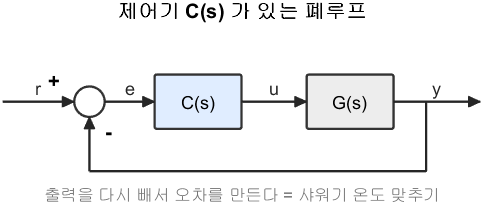

제어기가 있는 단위 되먹임 루프

**그림 파일** `loop_controller.png` — `common/dg_loop.m` 의 `dg_loop('controller')` · 다시 만들려면 `make_figures('loop_controller')`

먼저 **손으로** 해 보십시오. 30초면 됩니다.

- 플랜트의 극점은 어디입니까 ($0.5s+1 = 0$ 을 풀면 됩니다)

- 제어기의 영점은 어디입니까 ($150s+300 = 0$ 을 풀면 됩니다)

- 둘이 같습니까? 그러면 $L = PC$ 에서 무슨 일이 일어납니까

P = 0.2/(0.5*s + 1);
C = (150*s + 300)/s;

## 1-1. L 을 구하고 약분한다

`minreal` 은 분자와 분모의 공통 인자를 지웁니다. 손으로 약분한 결과와 같은지 보십시오. $L$** 이 아주 간단한 모양으로 나오면 맞은 것입니다.**

L = NaN;
% TODO : L = minreal(P*C);  로 바꾸십시오

if ~isa(L, 'tf')
    fprintf('  L 을 아직 안 구했습니다.\n');
else
    L
end

## 1-2. S 와 T, 그리고 네 숫자

정의는 이렇습니다. 강의노트 1-1절입니다.


$$S = \frac{1}{1+L}, \qquad T = \frac{L}{1+L}, \qquad S + T = 1$$


네 숫자는 이렇게 얻습니다.

if isa(L, 'tf')
    S = 1/(1 + L);
    T = L/(1 + L);

    gm = NaN; pm = NaN; wc = NaN; wb = NaN;
    % TODO : [gm, pm, ~, wc] = margin(L);   wb = bandwidth(T);  로 바꾸십시오

    if isnan(pm)
        fprintf('  네 숫자를 아직 안 채웠습니다.\n');
    else
        table(20*log10(gm), pm, wc, wb, ...
            'VariableNames', {'GM_dB', 'PM_deg', 'wc_rad_s', 'wb_rad_s'})
    end
end

## 1-3. 표 채우기 — 네 주파수에서 세 크기

주파수 네 개에서 $|L|$, $|S|$, $|T|$ 를 dB 로 읽습니다. **코드는 다 되어 있습니다.** 나오는 숫자를 보고 1-4절에 답하십시오.

if isa(L, 'tf')
    w = [0.6 6 60 600]';
    Ldb = 20*log10(abs(squeeze(freqresp(L, w))));
    Sdb = 20*log10(abs(squeeze(freqresp(S, w))));
    Tdb = 20*log10(abs(squeeze(freqresp(T, w))));
    table(w, Ldb, Sdb, Tdb, ...
        'VariableNames', {'w_rad_s', 'L_dB', 'S_dB', 'T_dB'})
end

## 1-4. 손으로 한 번 더 — 1 Hz 외란

강의노트 2-1절과 똑같은 계산입니다. $L = 60/s$ 이면


$$S(s) = \frac{1}{1 + 60/s} = \frac{s}{s+60}$$


이므로 $s = j\omega$ 를 넣으면


$$|S(j\omega)| = \frac{\omega}{\sqrt{\omega^2 + 60^2}}$$


$\omega = 2\pi$ (1 Hz) 를 손으로 넣어 보십시오. 계산기만 있으면 됩니다.

if isa(L, 'tf')
    S_hand = NaN;
    % TODO : S_hand = 2*pi/sqrt((2*pi)^2 + 60^2);  로 바꾸십시오

    if isnan(S_hand)
        fprintf('  손계산을 아직 안 넣었습니다.\n');
    else
        table(S_hand, abs(freqresp(S, 2*pi)), 20*log10(S_hand), ...
            'VariableNames', {'손계산', 'MATLAB', 'dB'})
    end
end

## 1-5. 답할 것 (각 한 문장)

- 이득여유가 `Inf` 로 나왔습니다. **왜** 그렇습니까? ($L = 60/s$ 의 위상은 모든 주파수에서 몇 도입니까)

- 위상여유가 정확히 $90$ 도입니다. 같은 이유입니까?

- $\omega_c$ 와 $\omega_b$ 가 거의 같습니다. 강의노트 3-3절에서 본 "$\omega_b \approx 1.5\,\omega_c$" 와 어긋나 보입니다. 왜 이 루프만 다릅니까?

- 1 Hz 외란은 폐루프를 지나면서 **몇 배**로 줄어듭니까? ($-19.65$ dB 를 배수로 바꾸면 됩니다)

**스스로 확인하는 법** — `dcgain(S)` 가 $0$ 이고 `dcgain(T)` 가 $1$ 이면 적분기가 제대로 들어간 것입니다.

## 2. 기본 — 사양을 만족하도록 PI 의 꺾이는 자리를 옮긴다

**강의노트 5-4절을 그대로 보면 됩니다.**

1번의 설계는 1 Hz 외란을 $-19.65$ dB 밖에 못 줄입니다. 현장에서 이것이 **부족하다**고 합니다. 사양이 이렇게 내려왔습니다.

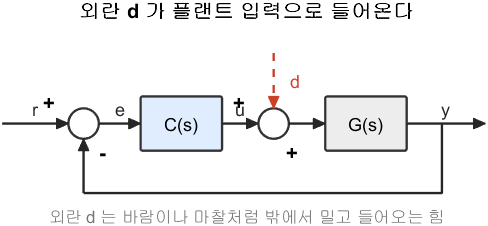

외란이 들어오는 폐루프

**그림 파일** `loop_disturbance.png` — `dg_loop('disturbance')` · 다시 만들려면 `make_figures('loop_disturbance')`

셋째 사양이 **왜 있는지**가 중요합니다. 외란만 보면 $|L|$ 을 그냥 크게 키우면 됩니다. 그런데 그러면 $\omega_c$ 가 같이 올라가고, 3번 문제에서 보듯이 **잡음이 따라 들어옵니다.** 그래서 "저주파만 올려라" 는 조건이 셋째 줄로 붙은 것입니다.

## 2-1. 무엇을 바꿀 수 있는가

PI 제어기를 강의노트 5-4절의 표기로 다시 씁니다.


$$C(s) = K\,\frac{T_i s + 1}{T_i s} = K\,\frac{s + 1/T_i}{s}$$


$K = 150$ 은 **그대로 둡니다.** 고주파 이득을 건드리면 $\omega_c$ 가 움직여서 셋째 사양이 깨집니다. 바꿀 수 있는 것은 **꺾이는 자리 **$1/T_i$ 하나뿐입니다.

- $1/T_i$ 를 **오른쪽으로** 옮기면 저주파 이득이 올라간다 (외란이 좋아진다)

- 대신 PI 의 음의 위상이 $\omega_c$ 까지 올라와 **PM 이 깎인다**

1번의 설계는 $1/T_i = 2$ 였습니다 ($150(s+2)/s$ 이므로). 여기서 오른쪽으로 옮겨 가며 재 봅니다.

K = 150;
corner = [2 5 10 20 30 40]';
m = numel(corner);
pm_v = zeros(m,1); wc_v = zeros(m,1); wb_v = zeros(m,1);
Sd_v = zeros(m,1); os_v = zeros(m,1);

for k = 1:m
    Ck = NaN;
    % TODO : Ck = K*(s + corner(k))/s;  로 바꾸십시오
    if ~isa(Ck, 'tf'), break, end

    Lk = minreal(P*Ck);
    [~, pm_v(k), ~, wc_v(k)] = margin(Lk);
    Tk = Lk/(1 + Lk);
    wb_v(k) = bandwidth(Tk);
    Sd_v(k) = 20*log10(abs(freqresp(1/(1 + Lk), 2*pi)));
    os_v(k) = stepinfo(Tk).Overshoot;
end

if all(pm_v == 0)
    fprintf('  제어기 Ck 를 아직 안 만들었습니다.\n');
else
    table(corner, K*corner, pm_v, wc_v, wb_v, Sd_v, os_v, ...
        'VariableNames', {'꺾이는자리', 'Ki', 'PM_deg', 'wc', 'wb', ...
                          '외란_1Hz_dB', 'OS_퍼센트'})
end

## 2-2. 합격선을 긋는다

표를 눈으로 보고 고르지 마십시오. **세 조건을 논리식으로** 써서 MATLAB 이 고르게 합니다. 7주차에서 `rl_scan` 으로 하던 것과 같은 방식입니다.

if any(pm_v ~= 0)
    ok = NaN;
    % TODO : ok = (Sd_v <= -30) & (pm_v >= 60) & (wc_v <= 72);  로 바꾸십시오

    if ~islogical(ok)
        fprintf('  ok 를 아직 안 채웠습니다.\n');
    elseif any(ok)
        fprintf('\n  합격한 꺾이는 자리 : ');
        fprintf('%g ', corner(ok));  fprintf('\n');
    else
        fprintf('\n  이 여섯 개 중에는 합격이 없습니다. 2-3절에서 더 촘촘히 훑으십시오.\n');
    end
end

## 2-3. 촘촘히 훑어 합격 구간의 양쪽 끝을 찾는다

합격하는 값이 **하나가 아니라 구간**입니다. 그 구간의 양쪽 끝이 어느 사양에 막혀 있는지가 설계자가 알아야 하는 것입니다.

**코드는 다 되어 있습니다.** 출력을 보고 2-4절에 답하십시오.

av = 15:0.5:60;
n = numel(av);
pm_s = zeros(n,1); wc_s = zeros(n,1); Sd_s = zeros(n,1);

for k = 1:n
    Lk = minreal(P*K*(s + av(k))/s);
    [~, pm_s(k), ~, wc_s(k)] = margin(Lk);
    Sd_s(k) = 20*log10(abs(freqresp(1/(1 + Lk), 2*pi)));
end

pass = (Sd_s <= -30) & (pm_s >= 60) & (wc_s <= 72);

fprintf('\n=== 합격 구간 ===\n');
if any(pass)
    fprintf('  1/Ti = %.1f 부터 %.1f 까지\n', min(av(pass)), max(av(pass)));
end

i1 = find(Sd_s <= -30, 1);
i2 = find(pm_s <  60,  1);
i3 = find(wc_s >  72,  1);
fprintf('  왼쪽 끝을 막는 것 : 외란 사양 (1/Ti = %.1f 에서 %.2f dB)\n', av(i1), Sd_s(i1));
fprintf('  오른쪽 끝을 막는 것 : PM 사양 (1/Ti = %.1f 에서 %.2f 도)\n', av(i2), pm_s(i2));
fprintf('  wc 사양은 1/Ti = %.1f 이 되어야 깨집니다 (%.2f rad/s)\n', av(i3), wc_s(i3));

## 2-4. 답할 것

- 합격 구간의 **왼쪽 끝**은 어느 사양에 막혀 있습니까? 오른쪽 끝은?

- $\omega_c$ 사양($72$ rad/s)은 합격 구간을 정하는 데 **쓰였습니까?** 쓰이지 않았다면 이 사양은 없어도 되는 것입니까? (힌트 — 3번 문제)

- 강의노트 5-4절의 실무 지침은 $1/T_i \approx \omega_c/10$ 입니다. 여기서는 $\omega_c = 60$ 이므로 $1/T_i = 6$ 입니다. 그 값은 합격입니까? **아니라면 지침이 틀린 것입니까?**

- 합격 구간 안에서 하나를 고르십시오. **왜 그 값인지** 한 문장으로 쓰십시오 (가운데를 고르는 것도 답이 됩니다. 이유를 쓰면 됩니다)

## 2-5. 고른 값으로 최종 확인

고른 $1/T_i$ 를 넣어 계단응답과 보드 선도를 보십시오.

corner_pick = 30;      % <-- 2-4 에서 고른 값으로 바꾸십시오

C_fin = K*(s + corner_pick)/s;
L_fin = minreal(P*C_fin);
T_fin = L_fin/(1 + L_fin);
S_fin = 1/(1 + L_fin);

[gm_f, pm_f, ~, wc_f] = margin(L_fin);
table(corner_pick, 20*log10(gm_f), pm_f, wc_f, bandwidth(T_fin), ...
      20*log10(abs(freqresp(S_fin, 2*pi))), stepinfo(T_fin).Overshoot, ...
      'VariableNames', {'고른_꺾이는자리', 'GM_dB', 'PM_deg', 'wc', 'wb', ...
                        '외란_1Hz_dB', 'OS_퍼센트'})

% 비교 기준은 1번의 설계, 즉 꺾이는 자리가 2 인 것입니다 (2-1절 참고)
L_base = minreal(P*K*(s + 2)/s);

figure;
tiledlayout(1, 2, 'TileSpacing', 'compact');

nexttile; hold on; grid on;
t = linspace(0, 0.2, 800)';
plot(t, step(L_base/(1+L_base), t), '--', 'LineWidth', 2, 'DisplayName', '1번 설계');
plot(t, step(T_fin, t), 'LineWidth', 2.2, 'DisplayName', '2번 설계');
yline(1, 'k:');
xlabel('시간 [s]'); ylabel('속도');
legend('Location', 'southeast'); title('계단응답 — 오버슈트가 생겼다');

nexttile; hold on; grid on;
wv = logspace(-1, 4, 500);
semilogx(wv, 20*log10(abs(squeeze(freqresp(1/(1+L_base), wv)))), '--', ...
    'LineWidth', 2, 'DisplayName', '1번 설계');
semilogx(wv, 20*log10(abs(squeeze(freqresp(S_fin, wv)))), ...
    'LineWidth', 2.2, 'DisplayName', '2번 설계');
xline(2*pi, 'k:', 'DisplayName', '1 Hz');
set(gca, 'XScale', 'log');
xlabel('주파수 [rad/s]'); ylabel('|S| [dB]');
legend('Location', 'southeast'); title('감도 — 저주파만 내려갔다');

## 2-6. 그림에서 확인할 것

- 오른쪽 그림에서 두 곡선이 **고주파에서는 겹치고** 저주파에서만 벌어지는 것을 확인하십시오. 그것이 "저주파만 올렸다" 는 증거입니다

- 왼쪽 그림에서 오버슈트가 생겼습니다. 이것이 **대가**입니다

- 1 Hz 세로선에서 두 곡선의 높이 차를 읽으십시오. 몇 dB 입니까?

## 3. 도전 (선택) — 대역폭을 키운 대가를 잡음으로 잰다

**강의노트 6절을 그대로 보면 됩니다.** 가산점 10점입니다.

2번에서 외란을 잡으려고 저주파 이득을 올렸고, 그 결과 $\omega_b$ 가 $59.9$ 에서 커졌습니다. 센서 잡음은 $n \to y$ 가 $-T$ 이므로 **대역폭 안의 잡음은 그대로 들어옵니다.** 얼마나 늘었는지 셉니다.

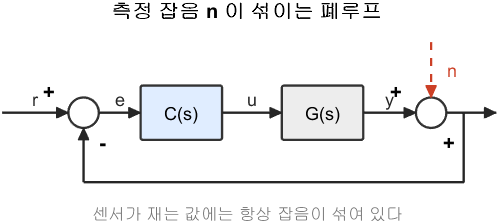

측정 잡음이 있는 폐루프

**그림 파일** `loop_noise.png` — `dg_loop('noise')` · 다시 만들려면 `make_figures('loop_noise')`

식은 이렇습니다. 샘플 간격 $T_s$ 로 만든 백색잡음의 표준편차가 $\sigma_n$ 일 때 출력에 남는 분산은


$$\sigma_y^2 = \frac{\sigma_n^2 \, T_s}{2\pi} \int_{-\pi/T_s}^{\pi/T_s} |T(j\omega)|^2 \, d\omega$$


입니다. 적분은 `trapz` 로 합니다.

- **[주의] 표준편차를 재려면 기록이 충분히 길어야 합니다.** 대역폭이 $60$ rad/s 이면 독립된 표본이 초당 $20$ 개 남짓입니다. $0.5$ 초짜리 기록으로는 $30\,\%$ 넘게 틀어집니다. 그래서 아래는 $20$ 초를 씁니다

Ts = 1e-4;
sig_n = 0.02;
t3 = (0:Ts:20)';
rng(2026);
noise = sig_n*randn(size(t3));

two = [2 40];
res = zeros(2, 4);

for k = 1:2
    Lk = minreal(P*K*(s + two(k))/s);
    Tk = Lk/(1 + Lk);

    sig_formula = NaN;
    % TODO : 아래 세 줄의 주석을 푸십시오
    % wgrid = linspace(-pi/Ts, pi/Ts, 200001);
    % mag2  = abs(squeeze(freqresp(Tk, abs(wgrid)))).^2;
    % sig_formula = sqrt(sig_n^2*Ts/(2*pi)*trapz(wgrid, mag2));

    y3 = lsim(Tk, noise, t3);
    res(k,:) = [bandwidth(Tk), sig_formula, std(y3), 100*std(y3)/sig_n];
end

if any(isnan(res(:,2)))
    fprintf('  적분식을 아직 안 넣었습니다. 실측만 나옵니다.\n');
end
table(two', res(:,1), res(:,2), res(:,3), res(:,4), ...
    'VariableNames', {'꺾이는자리', 'wb', 'sigma_y_식', 'sigma_y_실측', '남은_퍼센트'})

## 3-1. 답할 것

- 식과 실측이 몇 $\%$ 안에서 맞습니까?

- 대역폭이 $59.9$ 에서 $93.8$ 로 $1.57$ 배 커졌습니다. 잡음 표준편차는 몇 배 커졌습니까? **왜 **$1.57$** 배가 아닙니까?**

- 입력 잡음의 몇 $\%$ 가 출력에 남았습니까? 이 숫자를 보고 "되먹임이 잡음을 막아 준다" 고 말할 수 있습니까?

- 2-4절의 셋째 질문($\omega_c$ 사양이 왜 있는가) 에 **이제** 답하십시오

## 4. 제출

- 이 파일의 `TODO` 를 모두 채운 `.m` 파일

- 1-5 · 2-4 · 2-6 · 3-1 의 답 (한글 텍스트, 각 한두 문장)

- 2-5 의 그림 두 장

**채점 기준**

숫자만 맞고 **이유가 없으면 절반**입니다. 이 과제는 "왜 그 값인가" 를 묻는 과제입니다.